clear;clc;close all;

syms x y
f=(x-2)^2

$$f = {\left(x-2\right)}^{2}$$

df=diff(f,x)

$$df = 2\,x-4$$

xVal=0;
xOld=xVal(end);
rho=1/4;
for k=1:3
    xNew=xOld-rho*subs(df,x,xOld);
    xVal=[xVal;xNew];
    xOld=xVal(end);
end

xVal

$$xVal = \left[\begin{array}{c} 0\\ 1\\ 1.5000\\ 1.7500 \end{array}\right]$$

syms x [2,1]
x

$$x = \left[\begin{array}{c} x_{1}\\ x_{2} \end{array}\right]$$

J=x(1)^2/2+x(1)*x(2)/4+3*x(1)+x(2)^2/2+1

$$J = 0.5000\,{x_{1}}^{2}+0.2500\,x_{1}\,x_{2}+3\,x_{1}+0.5000\,{x_{2}}^{2}+1$$


rho=0.2;
dJdx1=diff(J,x(1))

$$dJdx1 = x_{1}+0.2500\,x_{2}+3$$

dJdx2=diff(J,x(2))

$$dJdx2 = 0.2500\,x_{1}+x_{2}$$


solVal=solve([dJdx1==0;dJdx2==0])

solVal = フィールドをもつ struct :
    x1: -3.2000
    x2: 0.8000


xVals=[3 3];
xOld=xVals(end,:);
xNew=[0 0];
z=[];
for k=1:20
    z=[z;subs(J,x,xOld')];
    xNew(1)=xOld(1)-rho*subs(dJdx1,x,xOld');
    xNew(2)=xOld(2)-rho*subs(dJdx2,x,xOld');
    xVals=[xVals;xNew];
    xOld=xNew;
end
z=[z;subs(J,x,xOld')];

xVals

xVals =     3.0000    3.0000
    1.6500    2.2500
    0.6075    1.7175
   -0.1999    1.3436
   -0.8271    1.0849
   -1.3159    0.9093
   -1.6982    0.7932
   -1.9982    0.7195
   -2.2345    0.6755
   -2.4214    0.6521



xVals(end,:)

ans =    -3.1092    0.7358


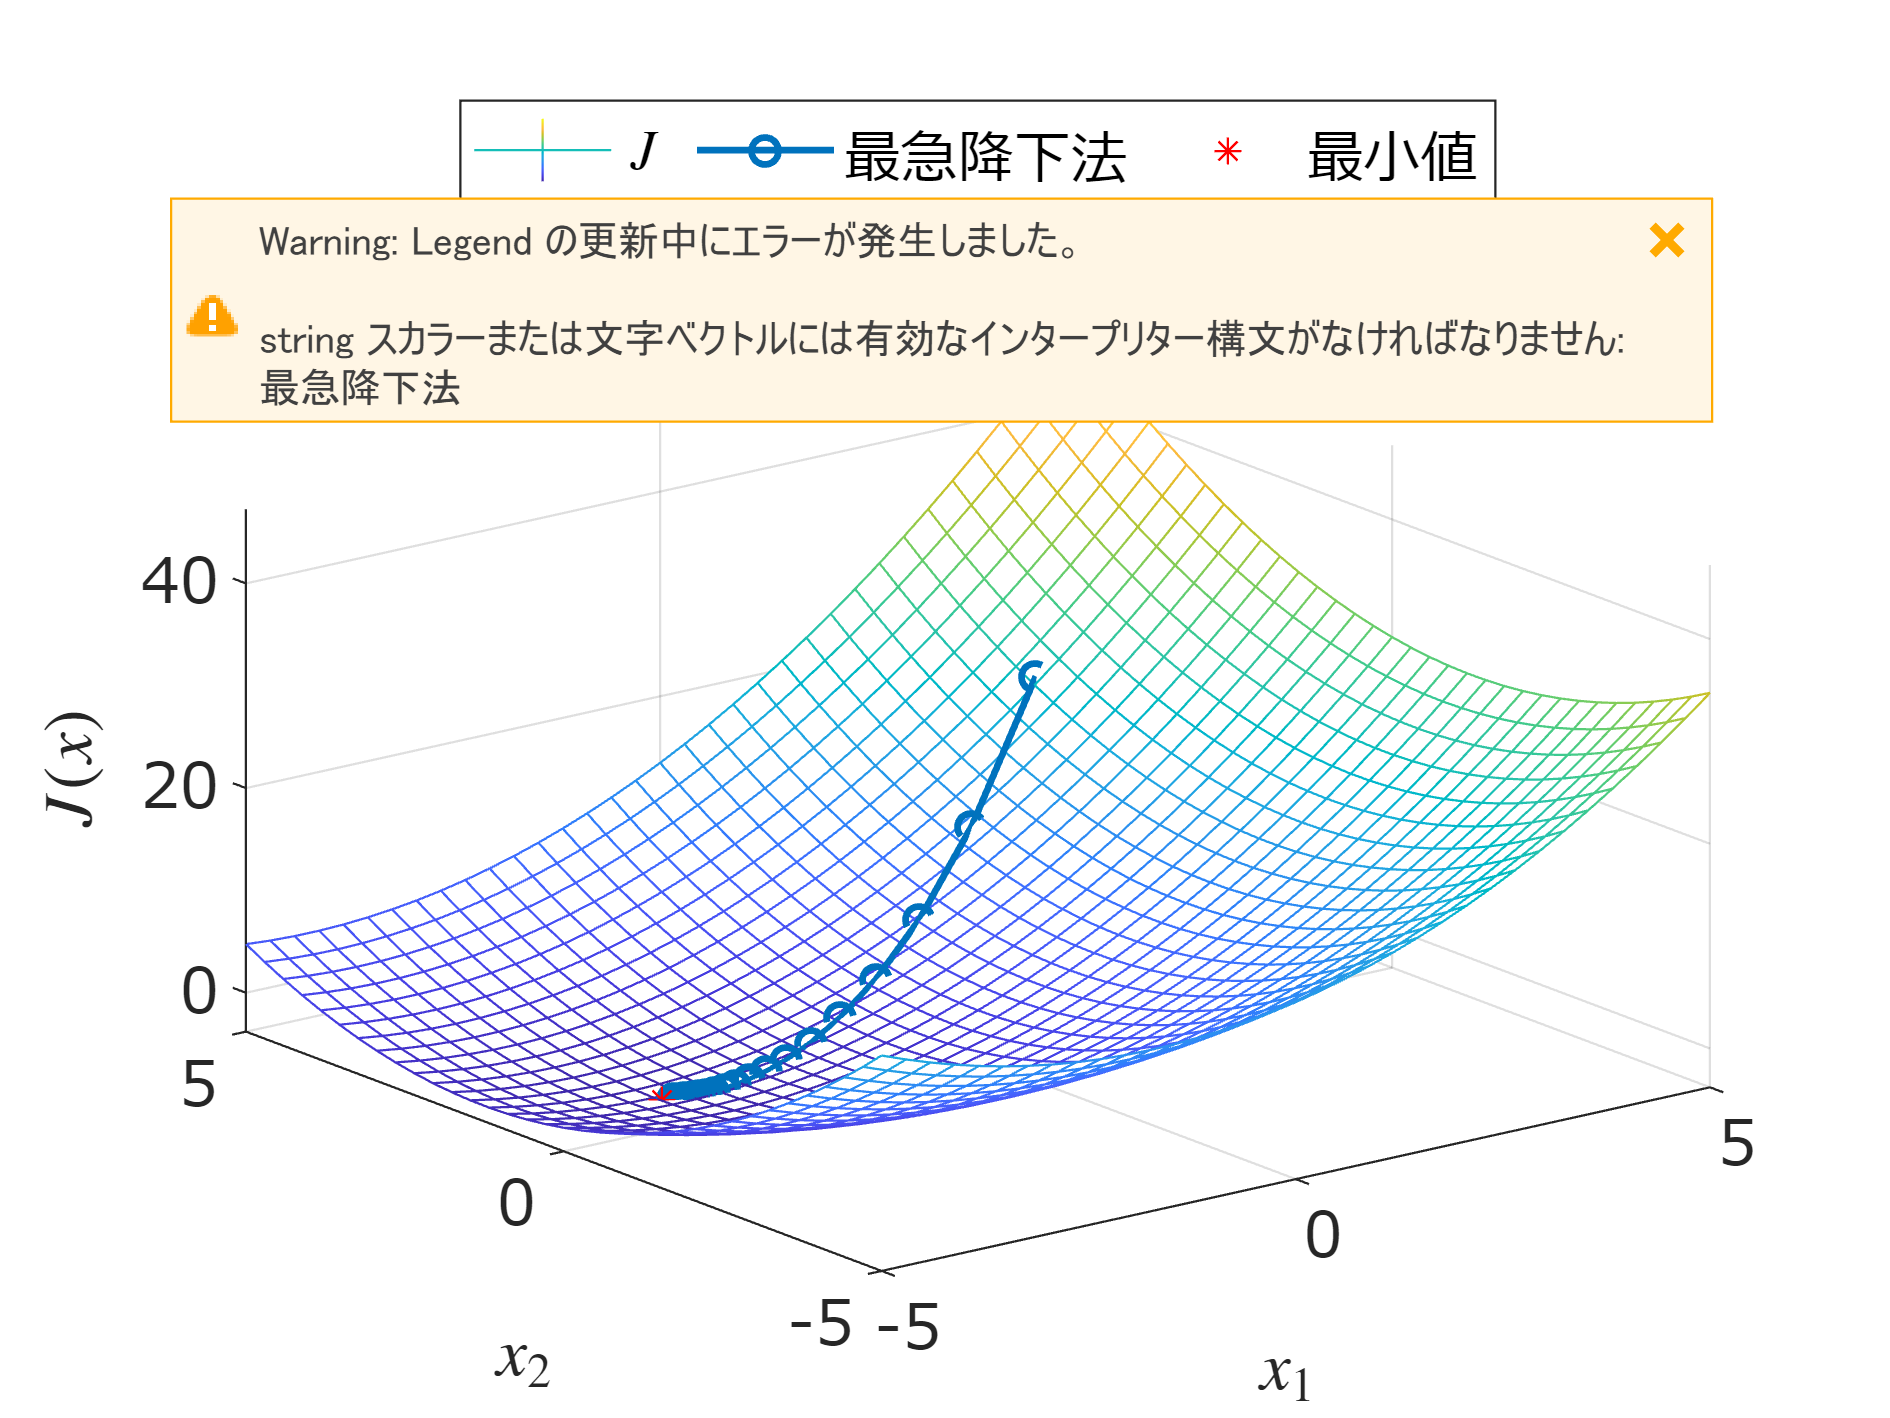


figure;
fmesh(J);
set(gca,'fontname','メイリオ','fontsize',14);
hold on;
xlabel('$x_1$','Interpreter','latex');
ylabel('$x_2$','Interpreter','latex');
zlabel('$J(x)$','Interpreter','latex');

plot3(xVals(:,1),xVals(:,2),z,'o-','linewidth',1.5);
plot3(solVal.x1, solVal.x2, subs(J,x,[solVal.x1;solVal.x2]), ...
    'r*')
title('メッシュ図と最急降下法');
legend({'$J$','最急降下法','最小値'},'Interpreter','latex', ...
    'Location','northoutside','Orientation','horizontal');

exportgraphics(gcf,'fig_Example_ChapA_SDM_mesh.pdf');

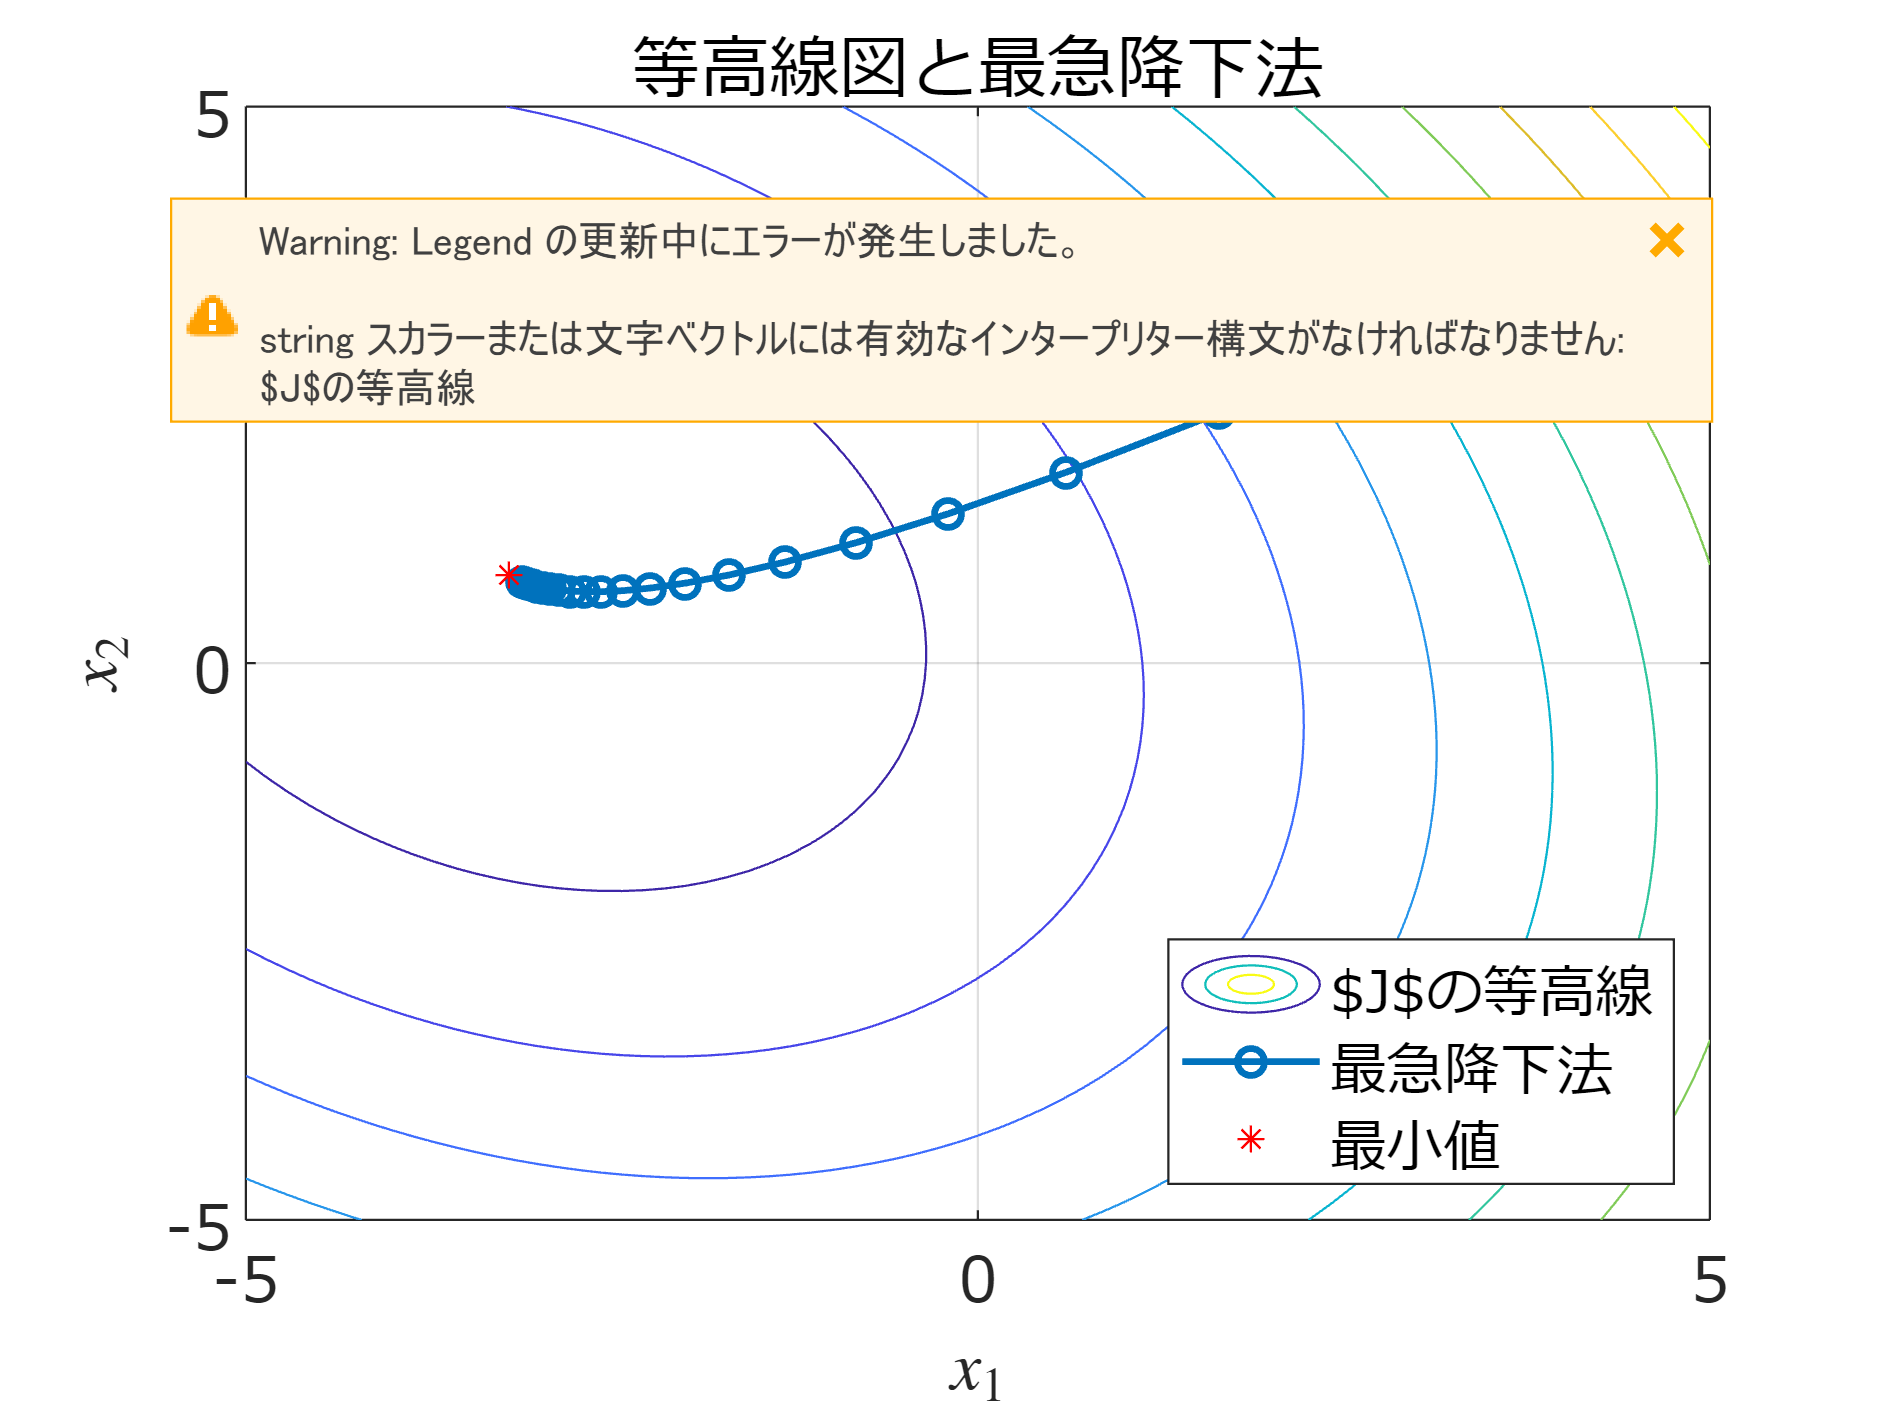


figure;
fcontour(J);
set(gca,'fontname','メイリオ','fontsize',14);
hold on;grid on;
plot(xVals(:,1),xVals(:,2),'o-','linewidth',1.5);
plot(solVal.x1, solVal.x2, 'r*');
legend({'$J$の等高線','最急降下法','最小値'},'Interpreter','latex','Location','southeast')
xlabel('$x_1$','Interpreter','latex');
ylabel('$x_2$','Interpreter','latex');
title('等高線図と最急降下法');
exportgraphics(gcf,'fig_Example_ChapA_SDM_contour.pdf');